## ANALYSIS OF MORE THAN 1 SAMPLE

GENERATE TWO SAMPLES

1st is spots1

decoded_file = 'G:\Tools-master\Analysis_functions\QT_0.4_details_noNNNN_ALL.csv';
image = 'G:\DIPG pciseq\Sample2\Base_2_aligned-1.tif';    % important for size
scale=1;
%% do not modify
% load
SPOTS1=ISS_getspots(decoded_file);
SPOTS1.image=image;
SPOTS1.scale=scale;
SPOTS1.output_directory='G:\outputfolder';
mkdir(SPOTS1.output_directory);

decoded_file = 'G:\Tools-master\Analysis_functions\QT_0.4_details_noNNNN_ALL.csv';
image = 'G:\DIPG pciseq\Sample2\Base_2_aligned-1.tif';    % important for size
scale=1;
%% do not modify
% load
SPOTS2=ISS_getspots(decoded_file);
SPOTS2.image=image;
SPOTS2.scale=scale;
SPOTS2.output_directory='G:\outputfolder';
mkdir(SPOTS2.output_directory);

And then we unite them

ALLSPOTS.SPOTS1=SPOTS1;
ALLSPOTS.SPOTS2=SPOTS2;

OVERLAPPING BINS CREATES A EXPRESSIONMAP

distance=400;
radius=800;
ALLEXPRESSION=ISS_OverlappingBins_moresamples(ALLSPOTS,distance,radius)

ISS_tsneRGB_several_samples(ALLEXPRESSION,ALLSPOTS.SPOTS1,minimumexp)

ISS_tsneRGB_several_samples(ALLEXPRESSION,ALLSPOTS.SPOTS1,100)



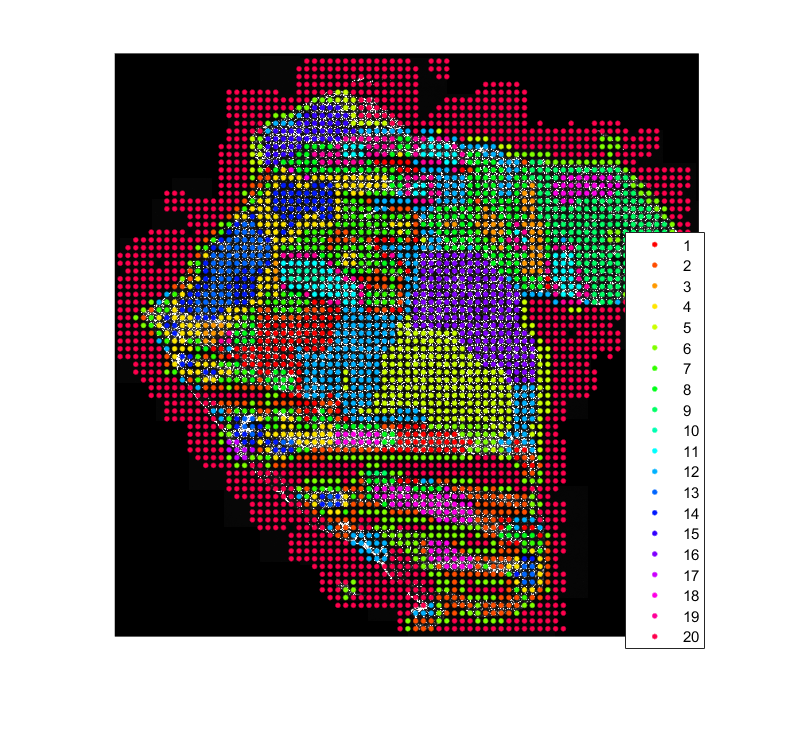

ALLCELLS = struct with fields:
    sample1: [1×1 struct]
    sample2: [1×1 struct]


[ALLCELLS]=ISS_hierarchical_clustering_several(ALLEXPRESSION,SPOTS,n_clust)

BI=ISS_Enviroment_neighbors_moresamples(SUPEROBJECT,radius)

     1

     1

     1

     1



BI = struct with fields:
           exp: [4×105 double]
           loc: [4×2 double]
      genename: {105×1 cell}
    hexbinsize: 6
        sample: [4×1 double]
         image: {'G:\DIPG pciseq\Sample2\Base_2_aligned-1.tif'  'G:\DIPG pciseq\Sample2\Base_2_aligned-1.tif'  'G:\DIPG pciseq\Sample2\Base_2_aligned-1.tif'  'G:\DIPG pciseq\Sample2\Base_2_aligned-1.tif'}
         scale: {[1]  [1]  [1]  [1]}
